# Sellmeier Analysis

% Run main.m for workspace
main;


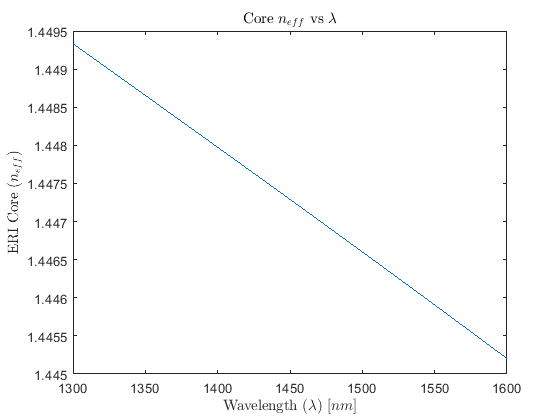

% Core Mode ERI
plot(i,temp1); title('Core $n_{eff}$ vs $\lambda$',"Interpreter","latex");
ylabel('ERI Core ($n_{eff}$)','Interpreter',"latex"); xlabel('Wavelength ($\lambda$) [$nm$]','Interpreter',"latex");

% Gradient
grad = diff(temp1)./diff(i') % y = -0.00001375x + c

grad = 	1.0e+-4 *

   -0.1357
   -0.1357
   -0.1357
   -0.1357
   -0.1357
   -0.1357
   -0.1357
   -0.1357
   -0.1357
   -0.1357


cros = temp1(1500)+0.00001375*i(1500) % 1.4672

cros = 1.4672

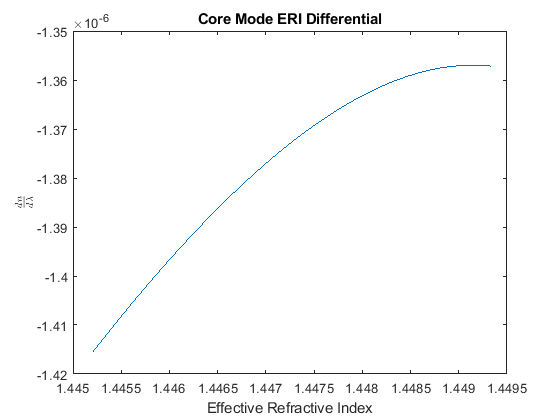

% Calculate diff of core mode ERI
df = diff(temp1);
plot(temp1(1:end-1),df); title("Core Mode ERI Differential");
xlabel("Effective Refractive Index"); ylabel("$\frac{dn}{d\lambda}$","Interpreter","latex");

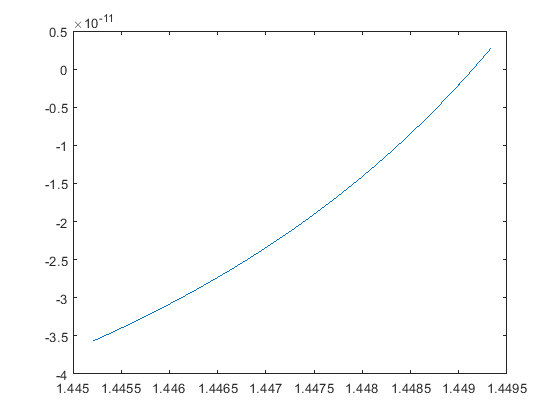


ddf = diff(df);
plot(temp1(1:end-2),ddf);

is_discont = ddf < 0;
n_discont = temp1(find(is_discont,1)) % point where discontinuity occurs

n_discont = 1.4491

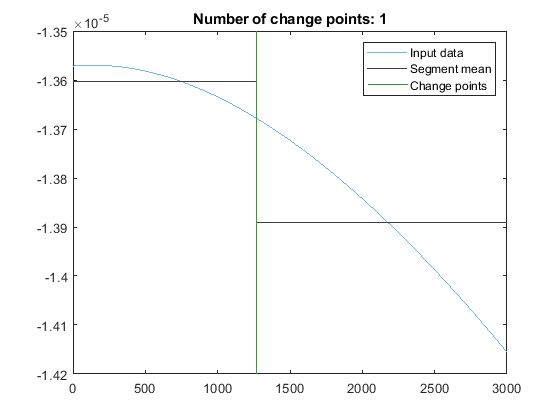

% Find change points
[changeIndices,segmentMean] = ischange(df,'variance','Threshold',length(df));

% Display results
clf
plot(df,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on

% Plot segments between change points
plot(segmentMean,'Color',[64 64 64]/255,'DisplayName','Segment mean')

% Plot change points
x2 = repelem(find(changeIndices),3);
y = repmat([ylim(gca) NaN]',nnz(changeIndices),1);
plot(x2,y,'Color',[51 160 44]/255,'LineWidth',1,'DisplayName','Change points')
title(['Number of change points: ' num2str(nnz(changeIndices))])

hold off
legend

clear segmentMean x2 y


## Selemeier Tests

## Cladding Analysis

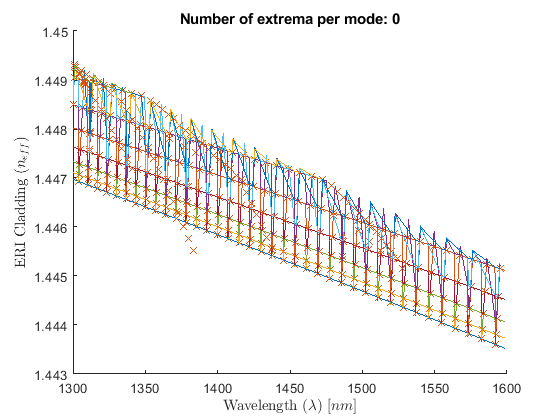

% Run main with mode=3
clf
maxima_mat = []; % Matrix of maxima y values
maxima_x = zeros(3000,num_cladding_modes);
wavelengths = 1300:step:1599;
% Find local maxima
hold on
for j = 1:15
    ERI = (~temp(:,j)==0);
    y_temp = temp(ERI,j);
    maxIndices = islocalmax(y_temp,'MinSeparation',6);
    plot(wavelengths(ERI),y_temp);
    maxima = y_temp(maxIndices);
    maxima_mat(1:length(maxima),j) = maxima;
    maxima_x(1:length(maxIndices),j) = maxIndices;
    % Plot local maxima
    plot(find(maxIndices)*step+1300,maxima,'x','Color',[217 83 25]/255,...
        'MarkerFaceColor',[217 83 25]/255,'DisplayName','Local maxima')
end
title(['Number of extrema per mode: ' num2str(nnz(maxIndices))]);
ylabel('ERI Cladding ($n_{eff}$)','Interpreter',"latex"); xlabel('Wavelength ($\lambda$) [$nm$]','Interpreter',"latex");
hold off

% Statistics on Cladding Maxima
for j = 1:num_cladding_modes
mode_1 = maxima_mat(:,2);
change_y = diff(mode_1);
fprintf("MEAN: %f",mean(change_y))
fprintf("MODE: %f",mode(change_y))
fprintf("MEDIAN: %f \n",median(change_y))

wavelengths = 1300:1599;
logic = logical(maxima_x(:,1));
lambda_x = wavelengths(logic);
change_x = diff(lambda_x);
fprintf("MEAN: %f",mean(change_x))
fprintf("MODE: %f",mode(change_x))
fprintf("MEDIAN: %f",median(change_x))

    
end

MEAN: -0.032157

MODE: 0.000000

MEDIAN: -0.000084 


The logical indices contain a true value outside of the array bounds.

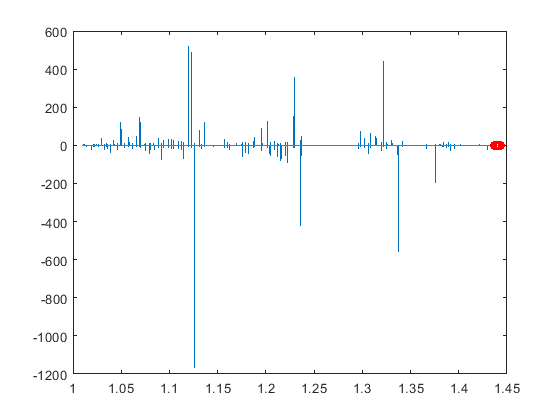

% Needed space for separation
plot(n_eff,real_0, n_eff, real_prime, intersections(:,1),intersections(:,2), 'ro');

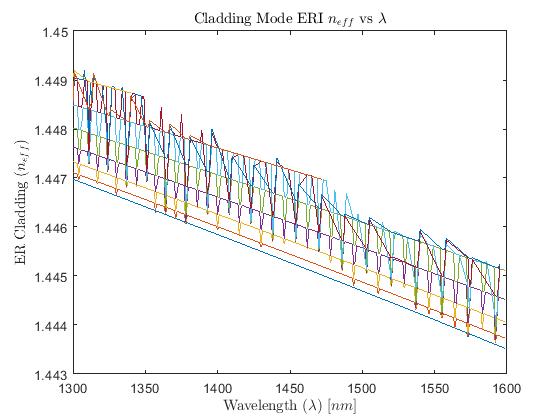

%clf(1)
ERI = (~temp(:,1)==0);
plot(i(ERI),temp(ERI,1));
hold on;
for j = 2:15
    ERI = (~temp(:,j)==0);
    plot(i(ERI),temp(ERI,j));
end
title('Cladding Mode ERI $n_{eff}$ vs $\lambda$',"Interpreter","latex");
ylabel('ER Cladding ($n_{eff}$)','Interpreter',"latex"); xlabel('Wavelength ($\lambda$) [$nm$]','Interpreter',"latex");
hold off

## Interpolation Analysis

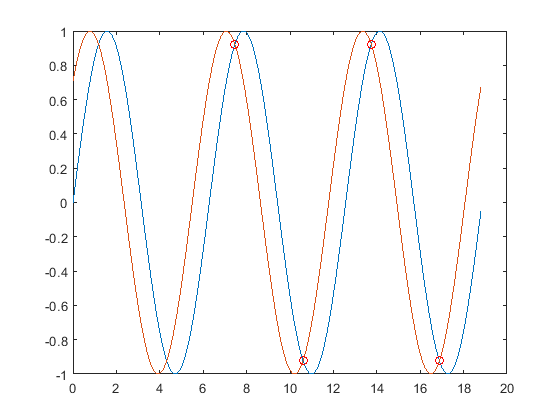

x1 = 0:0.1:6*pi;
y1 = sin(0:0.1:6*pi);
y2 = sin(pi/4:0.1:(6*pi+pi/4));
[inter, x, y] = find_intersections(x1, y1, y2, 4);

plot(x1,y1,x1,y2, inter(:,1),inter(:,2), 'ro');


%plot(temp);
